Advanced Topics in Control - Exercise 10 - iPendel

Institute for Electrical Engineering in Medicine

Dr.-Ing. Christian Hoffmann, Georg Männel, Marlin Siebert

13/07/2017

# iPendel H_inf Controller Synthesis

## Close all plots

clc
close all
clear variables

## Load Model Parameters

iPendelModelParameters

## Initial Values for the Simulation

theta0 =  pi/4;     %% Initial pendulum angle [rad]
dtheta0 = -pi/4;    %% Initial pendulum angular velocity [rad/s]
dphi0 =  1000;      %% Initial motor speed [rad/s]
r_theta   = 0;      %% Go to upright equilibrium
r_dtheta  = 0;      %% Go to upright equilibrium with constant velocity
r_dphi    = dphi0;  %% Keep initial motor speed

u_dist    = 100e-3; %% Disturbance

### Normalizing the system to prevent numerical instability

1. Create scaling parameters for input/output normalization

normalize_y = diag([1/(pi/4), 1/1000]); % Scale plant outputs such that y in [0, 1]
normalize_u = 1;

2. Define normalized Plant:

G_gen = G;
G_gen = normalize_y*G_gen*normalize_u;

## Exercise a)

- Appreciate that the plant model you are given is **equipped with uncertain parameters**. 

- (The file "iPendelModelParameters.m" shows how easy it is to incorporate such uncertainties.)

- However, initially, we are only interested in **synthesizing a controller for the nominal plant**, i.e., the plant for which the uncertainty is zero. 

1. **Obtain the nominal plant** from the given system *G* by using the *NominalValue* property

G_gen_0 = G_gen.NominalValue;

2.  **Plot the singular value** plot of both the nominal plant *G_gen_0* as well as the uncertain plant *G* (using *sigma*).

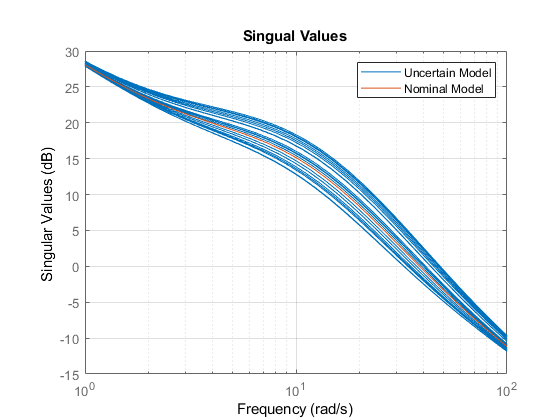

figure; sigma(G_gen, G_gen_0); 
title('Singual Values'); legend('Uncertain Model', 'Nominal Model')
grid on

As the given system is a **MIMO System** (2 inputs, 2 outputs), the sigma-plot values show the **maximum amplification** from the given system input to the output **idenpendent of the direction**!

## Exercise b) - Implement shaping filters

Overall goal: Define meaningful shaping filters for the sensitivity and control sensitivity.

### Recap of Lecture

#### Transferfunction of the closed loop that are shaped by using filters:

- **Sensitivity (S)**: Transferfunction from $r\to e$  or  $d\to y$

- **Complementary Sensitivity (T)**: Transferfunction from $r,n\to y$

- **Control Sensitivity (KS)**:Transferfunction from $r,n,\;d\to u$

- 
$$I=S+T$$


#### Control Objectives / Requirements:

- **Reference tracking**:              $T\to 1$ ($S\to 0$)

- **Disturbance rejection**:         $S\to 0$  ($T\to 1$)

- **Noise rejection**:                    $T\to 0$ ($S\to 1$)

- **Limit control effort**:             $|\mathrm{KS}|$ limited

        > Use frequency dependent filters to shape **S** to be **small for low frequencies** and to be **equal to 1** (or little higher) **for high freqencies**.

        > (With this, also **T** **is** **implicitly designed** **by S **to be euqal to 1 for low frequencies and small for high frequencies as $I=S+T$ holds.)

        > Use frequency dependent filter to shape **KS** to be **high for low frequencies** and **low for high frequencies** to prevent the controller to react on high frequent (measurement) noise 

#### Typical shape of $|S|$ and $\left|T\right|$:

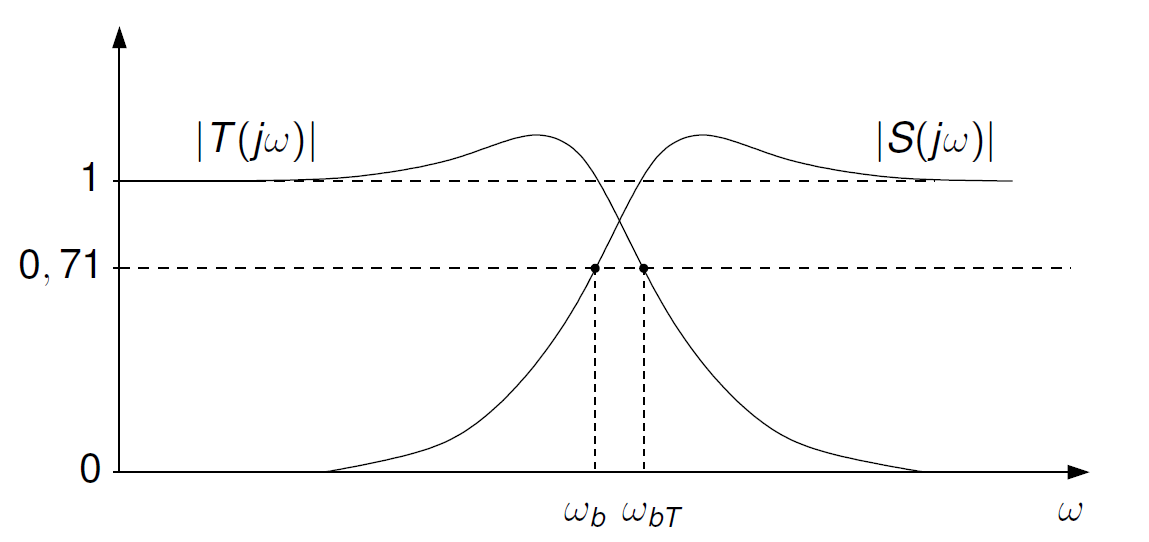

#### Control Design:

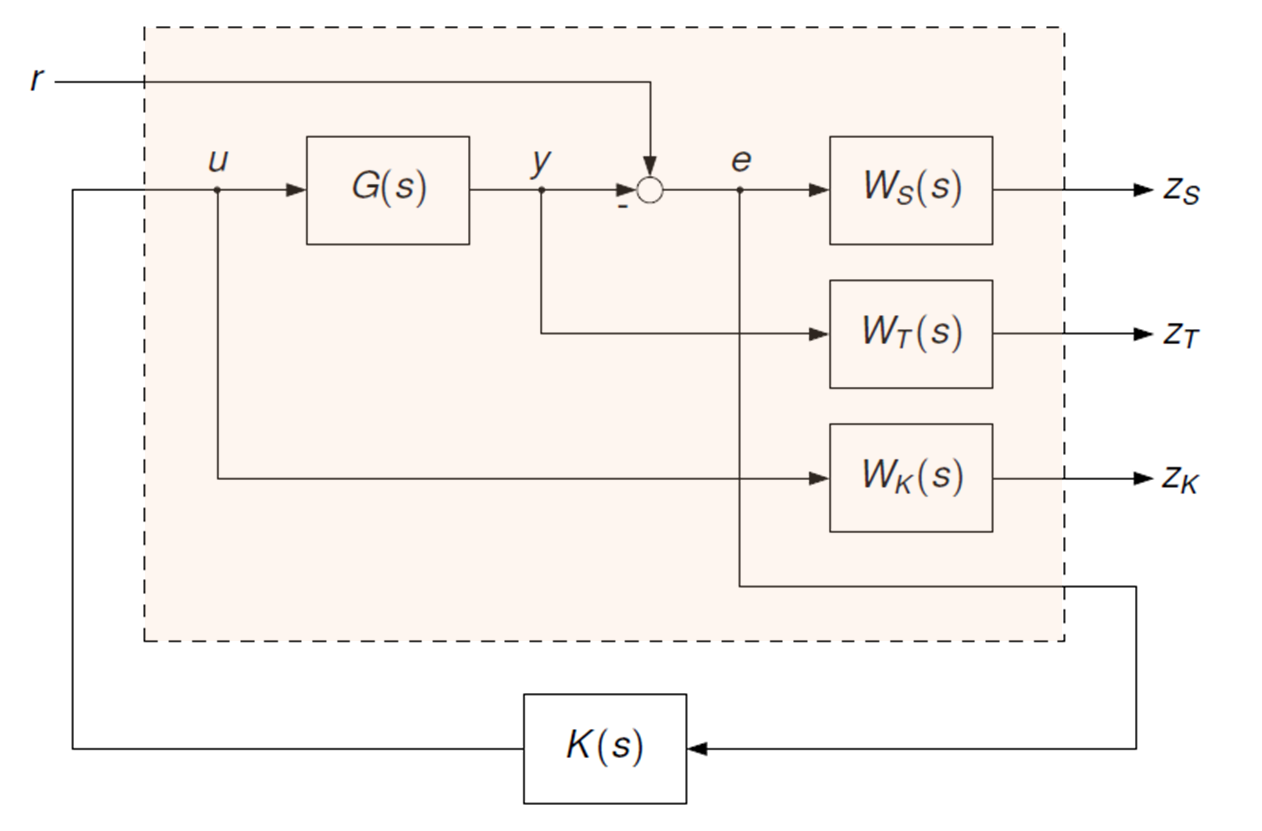

#### Mixed-Sensitivity Design: 

#### 
$$\|W_S \left(s\right)S\left(s\right){\|}_{\infty } <1\;\;\;\;\;\;\;\Leftrightarrow \;\;\;\;\;\sigma^‾ \left(S\left(j\omega \right)\right)<\frac{1}{|W_S \left(j\omega \right)|}\;\forall \omega$$


> Design filter such that the** inverse of the absolute of **$W_S$ can be** used as upper bound to the sensitivity** and the requirements can be met

### Implement Filter for given Requirements

#### Requirements

- **Maximal tracking error** of 1%

- **Minimal bandwidth** of the closed loop system for a) the angle of the iPendel at $1\;\mathrm{rad}/s$ and b) the engine speed at  $0\ldotp 1\;\mathrm{rad}/s$

- **Maximal control effort** is demanded to be smaller than $255\;\mathrm{mNm}$

#### Implementation

1. Define number of sensitivity and control sensitivity outputs. 

(This is useful for refering to in the Simulink model, when using "Mux" and "Demux" blocks.)

nzS  = 2;
nzKS = 1;

2. Define the sensitivity filter. **It has to be designed by 'matrix diagonalizing' two filters as the system has a two dimensional output.**

To match the requirements the **first filter** (with respect to the iPendle angle) has to be designed with 

- a ***dcgain *****at **${10}^2$ as $\frac{1}{{10}^2 }=0\ldotp 01\equiv 1%$,

- a **crossover frequency at **$1\;\mathrm{rad}/s$ and

- the ***hfgain***** at a little lower than 1**, e.g. 0.1 as we agian take the inverse of the filter to shape the Sensitivity

The **second filter** "gives control over the engine speed". Thus we change the **crossover frequency** compared to the first filter to $0\ldotp 1\;\mathrm{rad}/s$.

WS   = [makeweight(1e2, 1e0, 1e-1) 0; 0, makeweight(1e2, 1e-1, 1e-1)];

3. Define the control sensitivity filter. 

> To implement the shaping filter for the control sensitivity it is important to **allow the controller to amplify low frequency signals** to allow reference tracking but to **"ignore" high frequent noise**. 

> Thus we choose the ***dcgain***** low** and the ***hfgain***** high** (as the inverse filter gives the upper bound to the control sensitivity).

> The **crossover frequency** has to be **larger than for both the sensitivity filters**. If it would be lower the controller wouldn't amplify signals within the required bandwith!

WKS  = makeweight(1e-1, 5e1, 5e3);

4. Plot singular values of the inverse shaping filters with "sigma" to show the results.

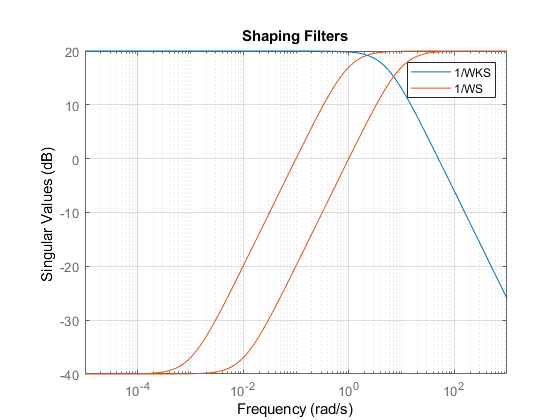

figure; sigma(1/WKS, 1/WS); title('Shaping Filters')
grid on
legend('1/WKS','1/WS')

## Exercise c) - Implement the generalized plant 

1. Open the model with using 'open generalizedPlantTemplate'.

open generalizedPlant
reply = input('Opened ''generalizedPlant''. Continue?\n1 - yes, 0 - no: ');
if reply == 0
   disp('No: Stopping Script')
   return;
end

2. **Build the generalized plant** into the provided template. Construct it in such a way as both sensitivity S and control sensitivity KS are shaped according to the implemented shaping filters WS and WKS.

> As the system can not be stabilized at an arbitrary angle, the reference for $\theta$ is set to constant zero. This also allows the ${\mathrm{H}}_{\infty }$-Synthesis to find a solution to the optimization problem because otherwise the system won't be stable.

## Exercise d) - Synthesize an H-infinity norm-optimal controller

Overall goal: Synthesize an H-infinity norm-optimal controller with respect to nominal system model.

1. Obtain a state-space system from the Simulink model representing the generalized plant (using *linmod).*

P = linmod('generalizedPlant');

2. Some "strange" behaviour requires the redefinition as a state-space model object.

P = ss(P.a, P.b, P.c, P.d);


3. Define the number of measured inputs received by the controller as well as the number of controlled inputs of the plant.

nv = size(G_gen_0, 1);
nu = size(G_gen_0, 2);


4. **Synthesize the controller** using *hinfsyn* along with the method *'lmi'*. 

> The optimization computes a controller **K** that minimizes the ${\mathrm{H}}_{\infty }$-Norm of the closed loop transferfunction from $w\to z:{\mathrm{T}}_{\mathrm{zw}}$ that is required to be smaller than 1:


$${\left\|{\mathrm{T}}_{\mathrm{zw}} \right\|}_{\infty } ={\left\|\left\lbrack \begin{array}{c}
W_{\mathrm{S}} \left(s\right)\mathrm{S}\left(s\right)\\
W_{\mathrm{K}} \left(s\right)\mathrm{KS}\left(s\right)
\end{array}\right\rbrack \right\|}_{\infty }$$


[K_inf, test, gamma, info] = hinfsyn(P, nv, nu, 'method', 'lmi', 'tolgam', 0.1);

5. Check if the controller fulfills the constraints by evaluating the achieved closed-loop H-infinity norm.

fprintf('Gamma is equal to %f\n', gamma);

Gamma is equal to 0.364868


In any case first proceed to the next section, in which the resulting closed-loop sensitivities are evaluated. These tell, in which way the shaping filters should be adapted, in order to make for realistic control objectives.

## Exercise e) - Evaluate Results

Overall goal: Plot the closed-loop sensitivities against the (inverse) shaping filters and validate with time-domain simulations!

1. Construct the closed-loop sensitivity and control sensitivity functions

- 
$$\mathrm{S}={\left(\mathrm{I}+\mathrm{G}\left(s\right)\mathrm{K}\left(s\right)\right)}^{-1}$$


- 
$$\mathrm{KS}={\mathrm{K}\left(s\right)\left(\mathrm{I}+\mathrm{G}\left(s\right)\mathrm{K}\left(s\right)\right)}^{-1} =\mathrm{K}\cdot \mathrm{S}$$


- 
$$\mathrm{T}={\left(\mathrm{I}+\mathrm{G}\left(s\right)\mathrm{K}\left(s\right)\right)}^{-1} \mathrm{G}\left(s\right)\mathrm{K}\left(s\right)=\mathrm{S}\cdot \mathrm{G}\cdot \mathrm{K}$$


S  = (eye(2) + G_gen_0*K_inf)^-1;
KS = K_inf*S;
T  = G_gen_0*K_inf*S;

2. Plot singular values of the closed-loop sensitivity and control sensitivity functions

> Only show the singular values from the second input to both outputs as the first input is chosen to be zero by default!

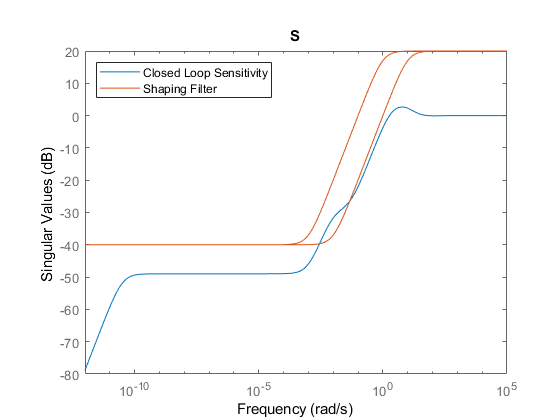

figure; sigma(S(:,2),  WS^-1); title('S'); legend('Closed Loop Sensitivity', 'Shaping Filter','Location','northwest')

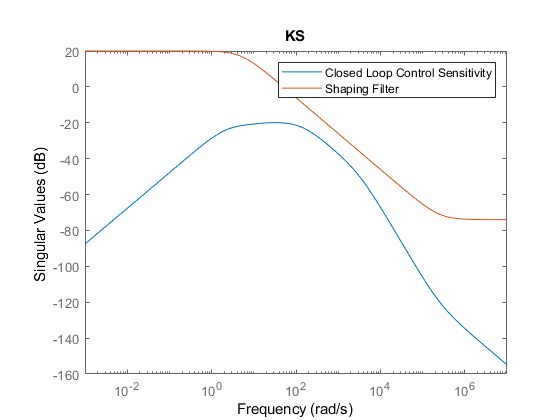

figure; sigma(KS(:,2),  WKS^-1); title('KS'); legend('Closed Loop Control Sensitivity', 'Shaping Filter')

3. Evaluate results by using the Simulink simulation model

sim('iPendulumHinf.slx')

> How does an external input disturbance change the system output?

   It causes a severe deviation of the system to the given reference as the controller does not expect any input disturbance to occur. 

   Thus, the designed controller is no longer optimal and the satisfaction of the requirements can no longer be guaranteed.

   (In this example the controller is still able to rebalance the iPendel but uses a lot more control input than it is allowed within the requirements.)

> How can the generalized plant be extended to improve the disturbance rejection of the controlled system?

   Using another input to the generalized plant that is added to the input to the system as done in *generalizedPlantDist.slx* acts as unknown input disturbance to the system.

   With this the controller is optimized to also cope with a disturbance (within the bandwith of the designed disturbance rejection) being posed on the input to the system.

open generalizedPlantDist
reply = input('Opened ''generalizedPlantDist''. Continue?\n1 - yes, 0 - no: ');
if reply == 0
   disp('No: Stopping Script')
   return;
end

## Exercise f) - Test Robustness

Overall goal: Evaluate the closed-loop H-infinity norm with respect to the uncertainty channel to check whether the requirements of the **small-gain theorem** are fulfilled and hence, **robust stability**. 

1. Separate the uncertain plant into an LTI system GM and a Delta block with **linear fractional transformation **(using *lftdata*).

[G_gen_cert, Delta] = lftdata(G_gen);

2. Define input and output size of the Delta block.

np = size(Delta, 2);
nq = size(Delta, 1);

3. Implement a simulink model of the generalized plant in which the above LTI system GM is used to explicitly take into account the uncertainty channel. 

open generalizedPlantDistwoF_unc
reply = input('Opened ''generalizedPlantDistwoF_unc''. Continue?\n1 - yes, 0 - no: ');
if reply == 0
   disp('No: Stopping Script')
   return;
end

Use *linmod* to extract the generalized plant in the form

PwoF_unc = linmod('generalizedPlantDistwoF_unc');
PwoF_unc = ss(PwoF_unc.a, PwoF_unc.b, PwoF_unc.c, PwoF_unc.d);

4. Attach the already synthesized controller of the nominal plant to the generalized plant PM (using *lft*). The result is

Tqzpw = lft(PwoF_unc, K_inf);

5. Calculate the H-Infinity norm of the uncertainty channel (using *hinfnorm*).

fprintf('H_inf of the uncertainty channel is equal to %f\n', hinfnorm(Tqzpw(1:nq, 1:np)));

H_inf of the uncertainty channel is equal to 1.067799


6. Plot singular values of the uncertain closed-loop sensitivity and control sensitivity functions. For this purpose reattach the Delta block to the system $\mathrm{TM}\left(s\right)$ (using *lft*).

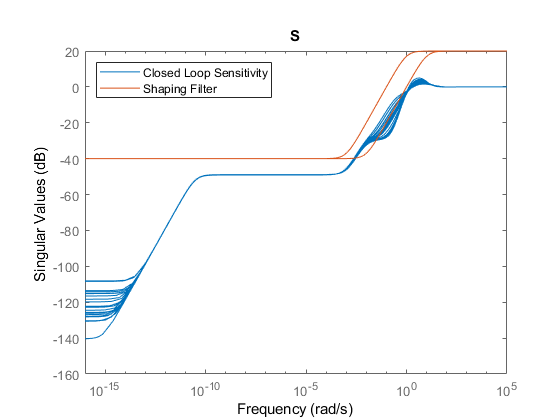

S_unc  = (eye(2) + G_gen*K_inf)^-1;
KS_unc = K_inf*S_unc;
T_unc  = G_gen*K_inf*S_unc;
figure; sigma(S_unc(:,2),  WS^-1); title('S'); legend('Closed Loop Sensitivity', 'Shaping Filter','Location','northwest')

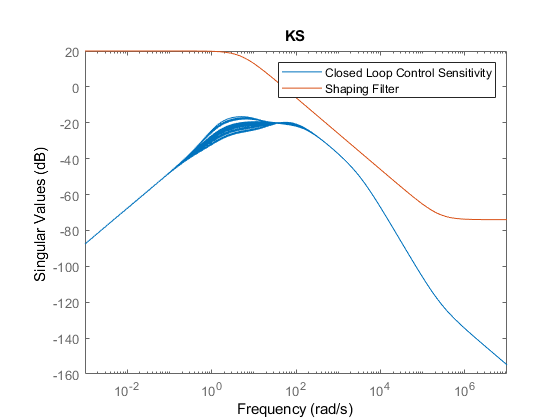

figure; sigma(KS_unc(:,2),  WKS^-1); title('KS'); legend('Closed Loop Control Sensitivity', 'Shaping Filter')